# Module 4: User-Defined Functions in MATLAB

Learning how to create and use user-defined functions in MATLAB is of significant importance, and here are some of the reasons:

- User-defined functions allow you to break your code into smaller, manageable modules.

- Once you've defined a function, you can reuse it in different parts of your code or even in multiple projects.

- Well-named functions can make the code easier for others (or your future self) to understand without delving into details.

- User-defined functions are easier to test and debug because you can isolate and test them individually.

## 1. Different Ways of Creating and Calling the Functions

### 1.1 [Anonymous Functions](https://www.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html)

One of the simplest ways in MATLAB to define and use functions in livescript/scripts, or even in command windows.

**Define** the anonymous function is just like create a variable -- it actually create a [function handle](https://www.mathworks.com/help/matlab/ref/function_handle.html?searchHighlight=functionhandle&s_tid=srchtitle_support_results_1_functionhandle) (recall that is a data type in MATLAB) in the workspace.

***Anonymous function handles***** (often called *****anonymous functions*****)** represent single inline executable expressions that return one output. 

To define an anonymous function, enclose input argument names in parentheses immediately after the `@` operator, and then specify the executable expression.

sqr = @(x) x.^2 ; 
class(sqr)

ans = 'function_handle'

**Call** the Function

sqr(1:4) % as if it is a MATLAB function you used before -- just like sin, cos, sqrt, exp

ans =      1     4     9    16


Here we use [fplot](https://www.mathworks.com/help/matlab/ref/fplot.html?searchHighlight=fplot&s_tid=srchtitle_support_results_1_fplot) to plot expression or a function

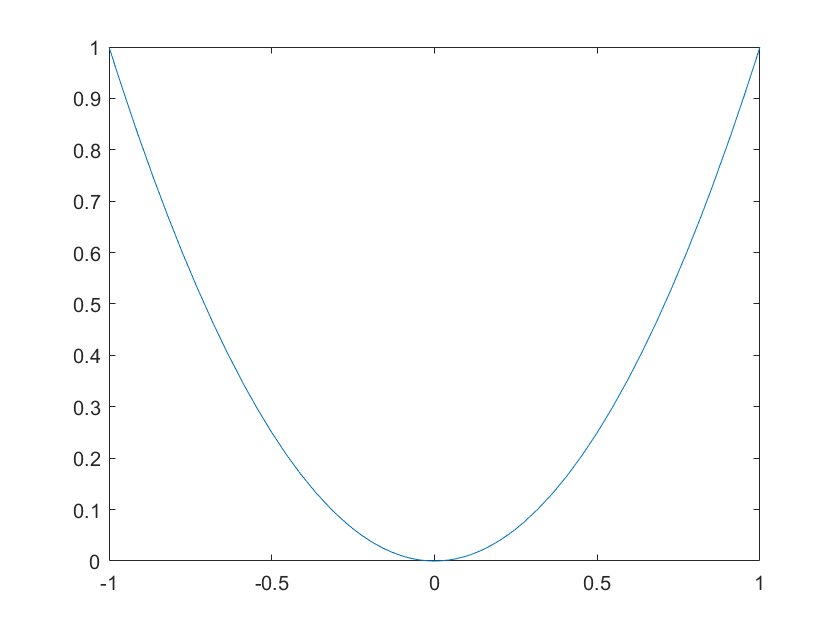

fplot(sqr,[-1 1]); % note the difference with plot

Anonymous functions can also use the existing variables in the work space

a = 1;
para = @(x) a*x.^2;
para(1:5)

ans =      1     4     9    16    25


However once created, they cannot be "updated" with the change of variables

a = 2;
para(1:5)

ans =      1     4     9    16    25


para = @(x) a*x.^2;
para(1:5)

ans =      2     8    18    32    50


### 1.2 [Function Files](https://www.mathworks.com/help/matlab/matlab_prog/create-functions-in-files.html) (as .m Files)

The function files can be understood as a special type of MATLAB script, allowing more flexibility with the input arguments and outputs.

***Example 1: a function without any function ***

edit myFunction1.m % open function file

help myFunction1

myFunction1 not found.

    Search the documentation for myFunction1



myFunction1() % call the function --nothing happens

myFunction1 is not found in the current folder or on the MATLAB path, but exists in:
    /Users/zbx/Desktop/Spring2025/Math9/week2

Change the MATLAB current folder or add its folder to the MATLAB path.

***Example 2: a function with an "useless" function***

edit myFunction2.m
myFunction2()

ans = 0

***Example 3: a function that calculates the element-wise square of input array x***

edit mysquare.m
mysquare(1:5)

ans =      1     4     9    16    25


### ***In-class Exercise 1 (***`dev_app.m`***)***

Open a new script file and write a function (named "dev_app") that calcuates the finite difference $\frac{f(x+h)-f(x)}{h}$ of $f(x)=x^2\sin(x)$, save your .m file as "dev_app.m" then run the command below to test your function:

x = 2;
dev = 2*x*sin(x) + x^2*cos(x);
dev_app(x, 0.00001)

ans =    1.972576622089050


dev_app(x, 0.00001) - dev

ans =     -2.573902510683013e-05


***Example 4: a more complicated case***

This function takes **another function** as input, and can have **multiple outputs** (see the function files for the format).

The input function should always be in the data type of [function handle](https://www.mathworks.com/help/matlab/matlab_prog/creating-a-function-handle.html), either created as anonymous function or a "normal function name" started with @.

The following function creates the evenly-spaced array x **from a to b with n points,** and assign the values of input function f at each point. Output: the arrays of values and points.

edit evaluatefunc.m
[yy, xx] = evaluatefunc(@(x)x.^3,1,5,10) % input the function as anonymous function

yy =     1.0000    3.0137    6.7394   12.7037   21.4335   33.4554   49.2963   69.4829   94.5418  125.0000


xx =     1.0000    1.4444    1.8889    2.3333    2.7778    3.2222    3.6667    4.1111    4.5556    5.0000


% note that the variable name when calling and defining the function does
% not need be exactly the same -- the position matters

[yy, xx] = evaluatefunc(sqr,1,5,10) % sqr is also the anonymous function we defined previously

yy =     1.0000    2.0864    3.5679    5.4444    7.7160   10.3827   13.4444   16.9012   20.7531   25.0000


xx =     1.0000    1.4444    1.8889    2.3333    2.7778    3.2222    3.6667    4.1111    4.5556    5.0000


[yy, xx] = evaluatefunc(@mysquare,1,5,10) % mysquare is the function we defined in file

yy =     1.0000    2.0864    3.5679    5.4444    7.7160   10.3827   13.4444   16.9012   20.7531   25.0000


xx =     1.0000    1.4444    1.8889    2.3333    2.7778    3.2222    3.6667    4.1111    4.5556    5.0000


% [yy, xx] = evaluatefunc(mysquare,1,5,10) % not a function handle!
% for matlab-defined functions, you also need to convert it to function handle at first by adding the @
[yy, xx] = evaluatefunc(@sin,1,5,10) 

yy =     0.8415    0.9920    0.9498    0.7231    0.3558   -0.0805   -0.5013   -0.8246   -0.9877   -0.9589


xx =     1.0000    1.4444    1.8889    2.3333    2.7778    3.2222    3.6667    4.1111    4.5556    5.0000


[yy, ~] = evaluatefunc(@sin,1,5,10) % omit the second output

yy =     0.8415    0.9920    0.9498    0.7231    0.3558   -0.0805   -0.5013   -0.8246   -0.9877   -0.9589


[~, xx] = evaluatefunc(@sin,1,5,10) % omit the first output

xx =     1.0000    1.4444    1.8889    2.3333    2.7778    3.2222    3.6667    4.1111    4.5556    5.0000


***Question: we have already defined "mysqure" function in a separate file, why still bother to write the @ in ***`evaluatefunc`*** example?***

When MATLAB sees "mysquare" , it by default understands that you want to call it, instead of passing it as the input. That's why you see the error message "missing arguments" when you forgot the @ sign. Therefore, @ sign "tells" MATLAB that you want to pass the function to another function as input, instead of directly calling it.

It can also be explained from the perspective of **workspace** or memory. It is true that mysquare.m is a file in the **current folder, **but there's no variable in current workspace representing that function. This is different with anonyomous function, which will authomatically create the function handle as variable in the workspace. Note that this won't be a issue if you direclly call a function -- it's just like running a script and you don't have to see that script in the workspace. But when you treat this function as the input to another function, there will be the problem --another function cannot "see" it in the workspace or MATLAB memory as other input variables!

func_hand = @mysquare % create another variable in workspace of type "function handle", representing the mysqure function defined in separate files

func_hand = function_handle with value:
    @mysquare


func_hand(1:3) % same as mysquare(1:3)

ans =      1     4     9


[yy, xx] = evaluatefunc(func_hand,1,5,10) % same as [yy, xx] = evaluatefunc(@mysquare,1,5,10)

yy =     1.0000    2.0864    3.5679    5.4444    7.7160   10.3827   13.4444   16.9012   20.7531   25.0000


xx =     1.0000    1.4444    1.8889    2.3333    2.7778    3.2222    3.6667    4.1111    4.5556    5.0000


**Take-home message**:

In Math 9, we use the @ sign (function handle) when 

1) we define an anonymous function;

2) we pass the function defined in .m files (or matlab-defined functions) as the input when calling another function, simply add the @ sign inside the parenthesis.

### ***In-class Exercise 2 (***`integral_left.m`***)***

Write a function file `integral_left(f, a, b, n) `which uses the left-end scheme to calculate numerical integral on evenly-spaced points, with the inputs as function handle f, partition number n, and integral interval from a to b, and outputs the value of approximated integral. Call the function to calculate $\int_0^5 x^3 e^{-x^2 } \textrm{dx}$ and compare with the [integral](https://www.mathworks.com/help/matlab/ref/integral.html?s_tid=doc_ta) function in Matlab.

a = 0;
b = 5;
n = 10;
func = @(x) x.^3.*exp(-x.^2);
value = integral_left(func, a, b, n)
integral(func,a,b)

### ***In-class Exercise 3 (***`diff_central.m`***)***

Write a function file `diff_central(f, a, b, n, h) `which uses the central scheme to calculate numerical derivative on evenly-spaced points, with the inputs as function handle f, total number of points n, and the step size in differentiation scheme `h`. The outputs should have three arrays: 1) the approximated derivatives at each point; 2) the function values at each point; 3) the coordinates of each point. 

Call the function to calculate the derivative of $x^3 e^{-x^2 }$ on the interval [0, 5] with 100 evenly spaced points and h chosen as 1e-2.

Plot the derivative functions and original functions with the results calculated with code below.

func = @(x) x.^3.*exp(-x.^2);
[der,val,x] = diff_central(func,0,5,100,0.01)
% use the code below to generate figures
plot(x,val,x,der);
legend('function value','derivative value')

### 1.3 **In-Script Functions**

If you don't want to define functions in sperate files, you can have everything included in the current livescript file. In this case, you need to define all the functions** at the end of this livescript**. 

The syntax is the same as define a .m function, and after they are defined, you can call them in the code blocks above them in the livescript. 

However, since these functions are not stored as separate files, they cannot be called by other livescripts or from the command lines.

***Example 5: write the "***`integral_right(f, a, b, n)" `***function using locally defined***` "mysquare_loc" function`

mysquare_loc(1:5)

ans =      1     4     9    16    25


integral_right(@mysquare_loc, 3,4,1e4)

ans = 12.3337

integral(@mysquare_loc, 3,4)

ans = 12.3333

integral_right(@(x)x.^3.*exp(-x.^2), 0,4,1e2)

ans = 0.5000

### ***In-class Exercise 4***

Define "`integral_left_loc(f,a,b,n)" `function at the end of this livescript and check if it works.

integral_left_loc(@(x)x.^3.*exp(-x.^2), 0,4,1e2)

ans = 0.5000

### 1.4 **Scopes of the Function**

By default, the variables defined inside functions are *local, *and do not interact with the global worksapce. 

This means input variables are copied when passing inside the function, and its value in global workspace (outside the function) won't be changed.

clear;
a = 5;
change_value(a)

ans = 100

a

a = 5

## 2. Other useful links

**Christopher Davis**’s videos about MATLAB: [https://www.youtube.com/playlist?list=PLHfGN68wSbbLOFWE0Z_uFLdXjax-evW-h](https://www.youtube.com/playlist?list=PLHfGN68wSbbLOFWE0Z_uFLdXjax-evW-h)

**Yasmeen Baki**’s videos about MATLAB: [https://www.youtube.com/playlist?list=PL6ue_xaI6w4NFUSQqGkzwnW1jJgfP5tNG](https://www.youtube.com/playlist?list=PL6ue_xaI6w4NFUSQqGkzwnW1jJgfP5tNG) 

## 3. **Functions defined in this livescript**

function y = mysquare_loc(x)
% this function is the same with mysquare, 
% the only difference is that it is defined at the end of this livescript instead of a seprate file.
% Every local functions in the livescript should be defined at the end

    y = x.^2;
end

function val = integral_right(f,a,b,n)
    x = linspace(a,b,n+1);
    h = (b-a)/n;
    f_val = f(x);
    val = h*sum(f_val(2:end));
end

function b = change_value(a)
    a = 100;
    b = a;
end